# **ACM 11 Week 8 In-class Exercise 1 (Spring 2021)**

## **Polynomial Interpolation: Runge phenomenon and Chebyshev points**

In this activity, we will construct polynomial interpolants of order $n-1$ using$n$ interpolation points for the function 

$y=\frac{1}{1+25x^2 }$.

**(0)  Group names: **

Dallas Taylor and Kyle McGraw

**(1a) The code block below walks through the implementation of polynomial interpolation in MATLAB. Follow the instructions to complete the code.**

n = 20 % Varying number of uniform equispaced meshpoints

n = 20

% (i) Generate x and y data for the function y = 1/(1+25x^2) on the interval [-1,1]
% using n equispaced points in the interval. Use linspace to select your
% x-points and then compute y at all x-points. 
x = linspace(-1,1,n); 
y = 1./(1 + 25 * x.^2);

% (ii) Construct the Vandermonde matrix,X, using your x points (the command VANDER can be used). 
% Use backslash to solve Xp = y for the polynomial coefficients p.
X = fliplr(vander(x));
p = X\transpose(y);

% (iii) on the provided plotting grid below (xplot), compute the true value
% of the function and also the value of your polynomial interpolant. When
% you are done, look at the provided plots.
xplot = linspace(-1,1,100); 
yexact = 1./(1 + 25 * xplot.^2);
yinterp = zeros(100,1);
for i = 1:100
    for j = 1:n
        yinterp(i) = yinterp(i) + p(j)* (xplot(i))^(j-1);
    end
end

The code block below plots the selected data points along with the exact function and the interpolating polynomial:

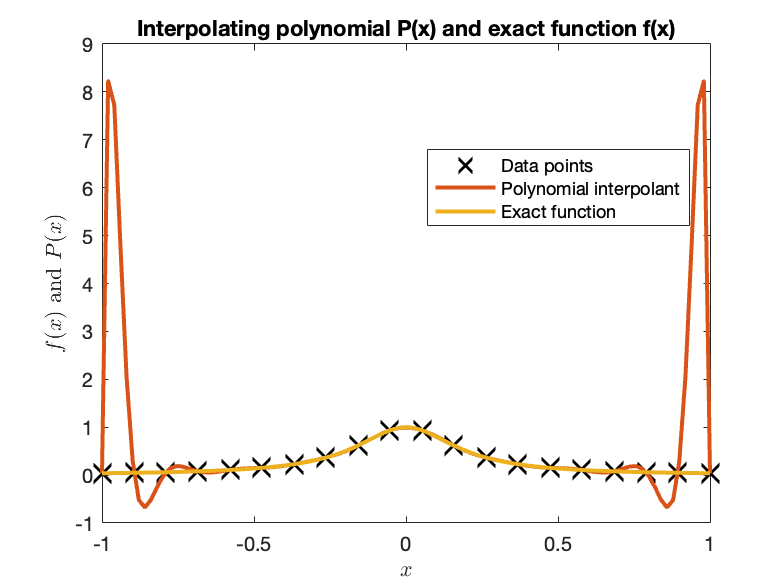

figure(1); 
plot(x,y,'kx','MarkerSize',10,'linewidth',2); hold on;
xlabel('$\theta$','interpreter','LaTex'); 
ylabel('$y$ ','interpreter','LaTex'); 
legend('Data points','Location','best')
set(gca,'fontsize',10); 
xlim([-1 1]);
plot(xplot,yinterp,'linewidth',2); hold on
legend('Data points','Polynomial interpolant','Location','best');
plot(xplot,yexact,'linewidth',2); hold off
legend('Data points','Polynomial interpolant','Exact function','Location','best')
xlabel('$x$','interpreter','LaTex')
ylabel('$f(x)$ and $P(x)$','interpreter','LaTex')
title('Interpolating polynomial P(x) and exact function f(x)')

The code block below plots the absolute difference between the exact function and the interpolating polynomial as a function:

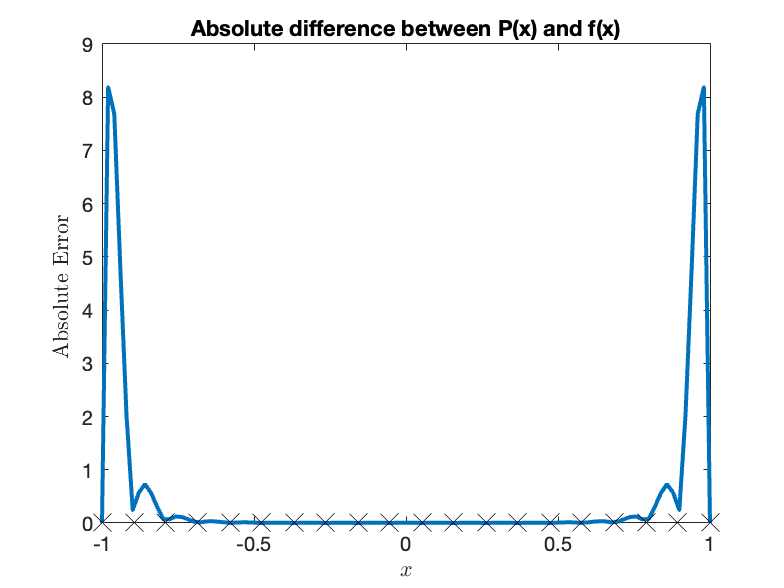

figure(2); clf
plot(xplot,abs(yexact-yinterp'),'linewidth',2); hold on
plot(x,zeros(size(x)),'kx','MarkerSize',10); hold off
xlabel('$x$','interpreter','LaTex'); 
ylabel('Absolute Error ','interpreter','LaTex'); 
set(gca,'fontsize',10); 
title('Absolute difference between P(x) and f(x)')

**(1b) Vary the number of interpolation points you use and look at what happens to the interpolant and its error. Where is the error smallest? Largest? Describe in 1-2 sentences what you observe as the number of interpolation points increases.**

The error is the smallest across all x values when we have n = 10 interpolation points.  The error is the largest across all x values when we have n = 30 interpolation points (~300 near poles). The error surrounding x = 0 decreases consistently as we increase n, however, the error surrounding the endpoints of our interval (-1 and 1) increases exponentially as we increase n. 

**(2a) What you have observed is called Runge's phenomenon. One solution to this problem is to evaluate the function at certain special points called "Chebyshev points" instead of equispaced points. For our **$\left\lbrack -1,1\right\rbrack$ **interval**,** the Chebyshev points are defined as follows:**

$x_k =\cos \left(\frac{\left(2k+1\right)\pi }{2n}\right)\;\;\;\textrm{for}\;\;0\le k\le n-1$.

**In the code block below, copy your interpolation code from above, but replace your equispaced x-data from above with the Chebyshev points given by the formula here. When you are done, run the code with different numbers of points (we have again provided plotting code for you; so don't change the variable names).**

n = 30 % Varying number of uniform equispaced meshpoints

n = 30

% (i) Generate x and y data for the function y = 1/(1+25x^2) on the interval [-1,1]
% using n equispaced points in the interval. Use linspace to select your
% x-points and then compute y at all x-points. 
x = zeros(n,1);
for i = 0:n-1
    x(i+1) = cos((2*i + 1)*pi/(2*n));
end
y = 1./(1 + 25 * x.^2);

% (ii) Construct the Vandermonde matrix,X, using your x points (the command VANDER can be used). 
% Use backslash to solve Xp = y for the polynomial coefficients p.
X = fliplr(vander(x));
p = X\y;

% (iii) on the provided plotting grid below (xplot), compute the true value
% of the function and also the value of your polynomial interpolant. When
% you are done, look at the provided plots.
xplot = zeros(100,1);
for i = 0:100-1
    xplot(i+1) = cos((2*i + 1)*pi/(2*100));
end
yexact = 1./(1 + 25 * xplot.^2);
yinterp = zeros(100,1);
for i = 1:100
    for j = 1:n
        yinterp(i) = yinterp(i) + p(j)* (xplot(i))^(j-1);
    end
end

The code block below plots the selected data points along with the exact function and the interpolating polynomial:

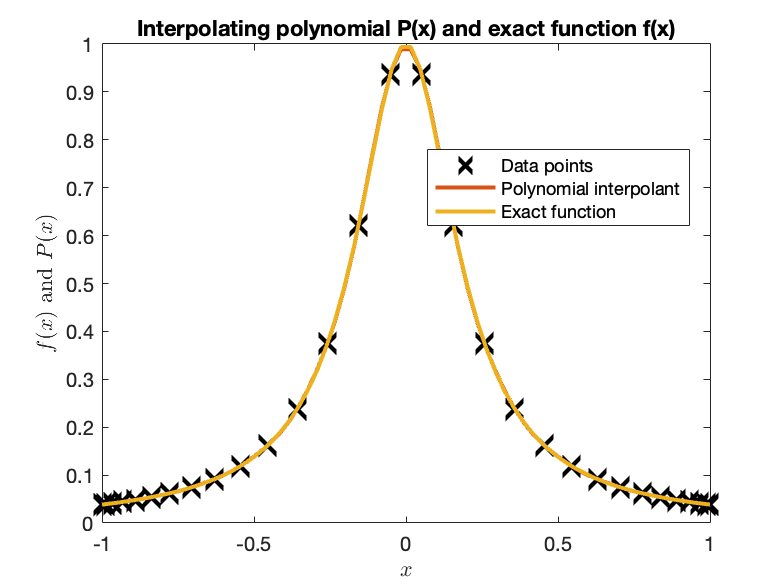

figure(3); 
plot(x,y,'kx','MarkerSize',10,'linewidth',3); hold on;
xlabel('$\theta$','interpreter','LaTex'); 
ylabel('$y$ ','interpreter','LaTex'); 
legend('Data points','Location','best')
set(gca,'fontsize',10); 
xlim([-1 1]);
plot(xplot,yinterp,'linewidth',2); hold on
legend('Data points','Polynomial interpolant','Location','best');
plot(xplot,yexact,'linewidth',2); hold off
legend('Data points','Polynomial interpolant','Exact function','Location','best')
xlabel('$x$','interpreter','LaTex')
ylabel('$f(x)$ and $P(x)$','interpreter','LaTex')
title('Interpolating polynomial P(x) and exact function f(x)')

The code block below plots the absolute difference between the exact function and the interpolating polynomial as a function:

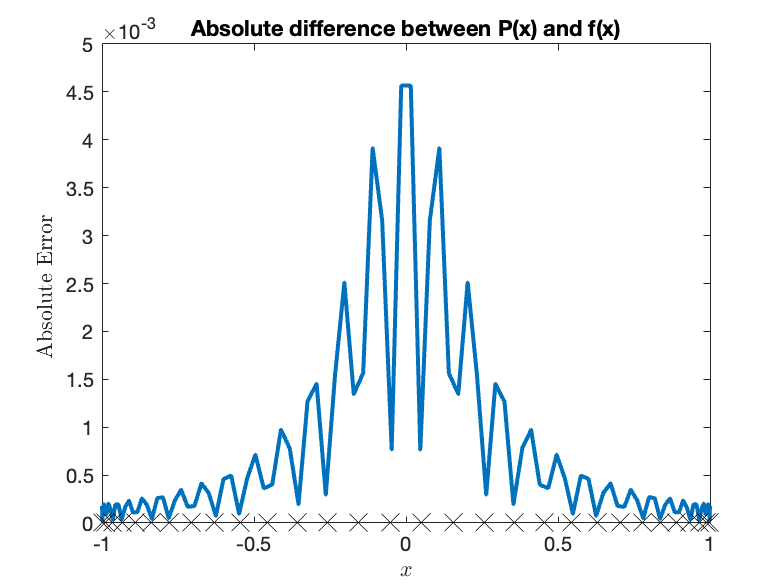

figure(4); clf
plot(xplot,abs(yexact-yinterp),'linewidth',2); hold on
plot(x,zeros(size(x)),'kx','MarkerSize',10); hold off
xlabel('$x$','interpreter','LaTex'); 
ylabel('Absolute Error ','interpreter','LaTex'); 
set(gca,'fontsize',10); 
title('Absolute difference between P(x) and f(x)')

**(2b) In 1-2 sentences, describe what you observe using Chebyshev points and how it differs from using equispaced points.**

Here, we observe that the Chebyshev points result in a much lower absolute error across all n values (other than a slightly similar error for n = 5).  Additionally, the polynomial interpolant more closely matches the exact function across all n values.  Thus, the Chebyshev points behave better than equispaced points.